# **RS-EO-06 MDP Structure Design**

**UT Austin Aerospace Engineering**

**Hongseok Kim**

**10/21/24**

## I. Load the Dataset

% addpath('~/Desktop/Redstone_Project/RS_EO/RS_EO_05_Satellite_Network_Design/')
% addpath('~/Desktop/Redstone_Project/RS_EO/RS_EO_06_MDP_Structure_Design/')
% load('state_transition_matrix.mat');
% load('state_reward_matrix.mat');
% 
% 
% state_transition_matrix;
% state_reward_matrix;
% 

## II. Proceed MDP Policy Iteration Algorithm

% time_index_vector = 1:100;
% 
% 
% %% Configure MDP Structure (Level 1 - 6)
% MDP = config_MDP_struct(state_transition_matrix,state_reward_matrix, time_index_vector);
% 
% %% Policy Iteration Process for Last Timestep
% number_of_states = length(state_transition_matrix(1,:,1));
% 
% pi_distribution = zeros(number_of_states);
% policy_iteration_count = 1;
% gamma = 1;
% 
% while true
% 
%     MDP = policy_evaluation_process(MDP, time_index_vector,state_transition_matrix, policy_iteration_count,gamma);
% 
%    [MDP,pi_distribution_updated] = policy_improvement_process(MDP,time_index_vector, state_transition_matrix);
% 
%    if pi_distribution == pi_distribution_updated
%        break;
%    end
% 
%    pi_distribution = pi_distribution_updated;
%    policy_iteration_count = policy_iteration_count +1;
% 
% end
% 
% MDP.(['time' num2str(max(time_index_vector))]).policy_distribution = pi_distribution;
% 
% %% State and Action value propagation to t_n-1 ... t_1
% MDP = value_function_propagation(MDP,time_index_vector,state_transition_matrix, gamma);

## III. State Value Change Over Time

% state_vector = 1:60;
% 
% state_change_value_matrix = zeros(length(time_index_vector),length(state_vector));
% 
% for time_index = time_index_vector
%     for state_index = state_vector
%         state_value_number = MDP.(['time' num2str(time_index)]).(['state' num2str(state_index)]).('state_value');
%         state_change_value_matrix(time_index-min(time_index_vector)+1,state_index) = state_value_number;
%     end
% end
% figure;
% hold on
% for state_index = state_vector
%    plot(time_index_vector,state_change_value_matrix(:,state_index),'LineWidth',1)
% end
% hold off
% title('State Value Change (4 Ground Stations)','FontSize',18,'FontWeight','bold')
% xlabel('timestep (x15 seconds)','FontSize',15,'FontWeight','bold')
% ylabel('state value','FontSize',15,'FontWeight','bold')

## IV. Propate the States from given start time and start state

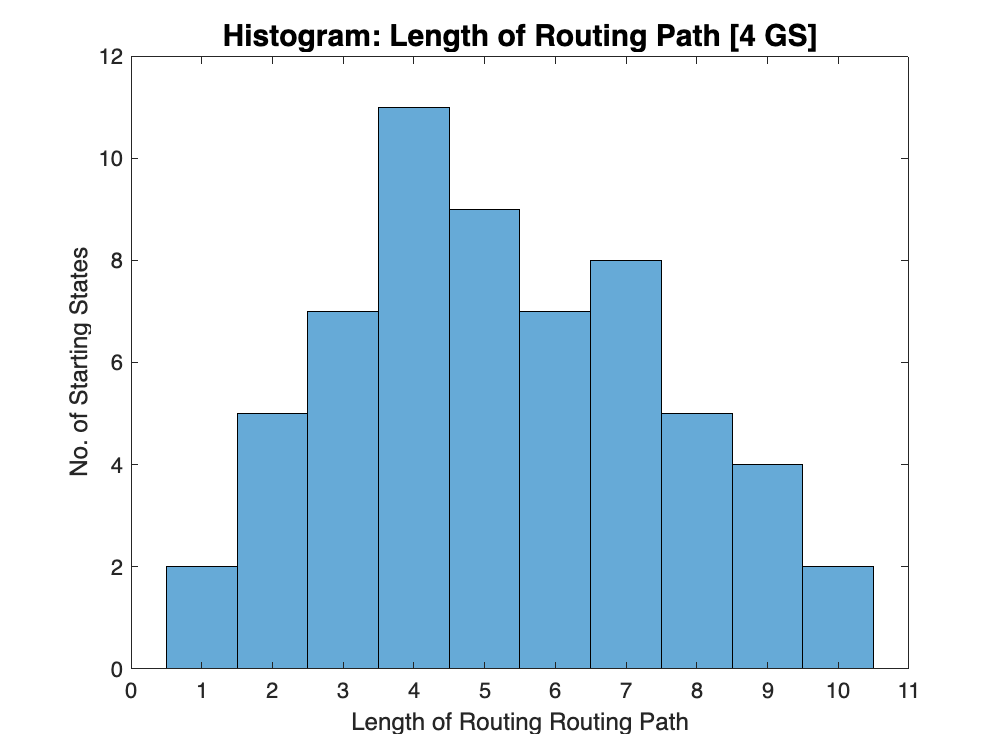


load('~/Desktop/Redstone_Project/RS_EO/RS_EO_02_Constant_Area_Capture/data_generation.mat')

arrival_state = 61:72;
% 
% start_time_vector = [100, 150, 200, 250, 100, 130, 140, 270, 130, 90];
% start_state_vector = [ 1,  10,  34,  20,  51,  31,  35,  31,  34, 60];

% start_state_vector = data_generation(:,1);
% start_time_vector = data_generation(:,2);

start_time_vector = 50*ones(1,60);
start_state_vector = 1:60;

state_matrix = zeros(length(time_index_vector), length(start_state_vector));
reward_matrix = zeros(length(time_index_vector), length(start_state_vector));
cumulative_reward_matrix = zeros(length(time_index_vector), length(start_state_vector));
state_value_matrix = zeros(length(time_index_vector), length(start_state_vector));

% Result Display
length_of_routing_path_vector = zeros(length(start_state_vector),1);
state_value_vector_for_starting_state = zeros(length(start_state_vector),1);

for start_state_index = 1:length(start_state_vector)

  start_state = start_state_vector(start_state_index);
  start_time = start_time_vector(start_state_index);
    
  [time_list, state_list, reward_list, cumulative_reward_list, state_value_list] = simulation_test(start_time,start_state,MDP,time_index_vector, arrival_state);
  A =  [time_list, state_list, reward_list];

  for time_index = 1:length(time_list)
    state_matrix(time_list(time_index), start_state) = state_list(time_index);
  end
  
  t_0 = time_list(1);
  reward_matrix(t_0:t_0+length(reward_list)-1, start_state) = reward_list;
  cumulative_reward_matrix(t_0:t_0+length(cumulative_reward_list)-1, start_state) = cumulative_reward_list;
  state_value_matrix(t_0:t_0+length(state_value_list)-1, start_state) = state_value_list;

 length_of_routing_path_vector(start_state_index) = length(state_list) - 1;
 state_value_vector_for_starting_state(start_state_index) = state_change_value_matrix(start_time, start_state);
end



histogram(length_of_routing_path_vector)
title('Histogram: Length of Routing Path [4 GS]','FontSize',15,'FontWeight','bold')
xlabel('Length of Routing Routing Path')
ylabel('No. of Starting States')

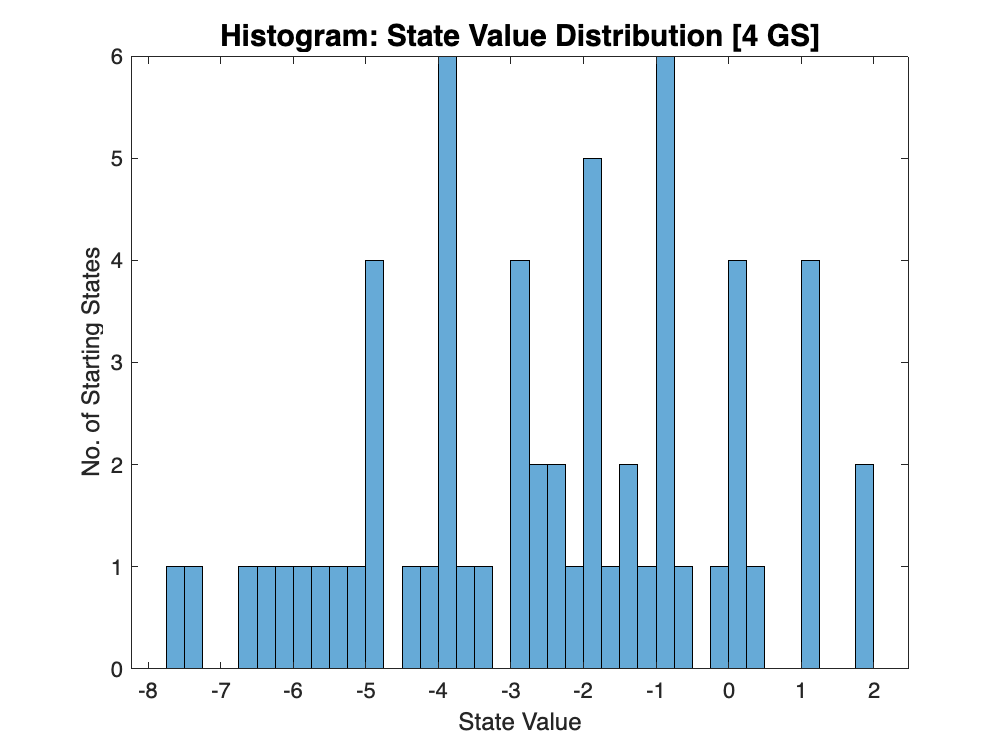




histogram(state_value_vector_for_starting_state,'BinWidth',0.25)
title('Histogram: State Value Distribution [4 GS]','FontSize',15,'FontWeight','bold')
xlabel('State Value')
ylabel('No. of Starting States')



mean_state_value = mean(state_value_vector_for_starting_state)

mean_state_value = -2.5304

std_state_value = std(state_value_vector_for_starting_state)

std_state_value = 2.3738

mean_length = mean(length_of_routing_path_vector)

mean_length = 5.2667

std_length = std(length_of_routing_path_vector)

std_length = 2.2912

## V. Plot the Network Graph